# Spring-Mass Chain

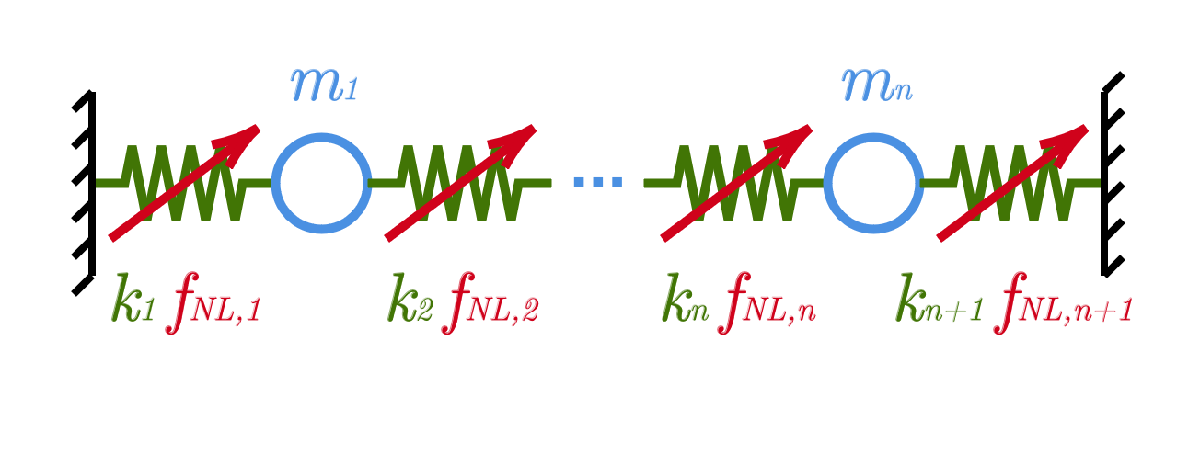

## Initialize

Include the function folder.

addpath(genpath(fullfile('..', 'LSM-opt-functions')))

## Settings

Define the type of the system.

sysArgs.systemType = @SystemSpringMassChain;

Define the boundary conditions: 0 to fix the mas, 1 to let it free.

sysArgs.bc = [0, ones(1, 3), 0];
nMasses = sum(sysArgs.bc);
nSprings = nMasses + 1;

Define the index of the target mode.

sysArgs.modeIndex = 1;

Define the LSM arguments, i.e., the target dof of the system and the LSM expansion order.

lsmArgs.iDof = 2;
lsmArgs.order = 5;

## Optimization problem

The objective function and the nonlinear constraints are defined in the `fun` and `nonlcon` functions in this folder. 

Define the target points as frequency - amplitude pairs.

optArgs.omegaTarget = [2, 1.9, 2.1];
optArgs.zTarget = [0, 1.5, 2];

Specify if the frequency - amplitude pairs are treated as equality constraint (0), upper inequality constraint (1), or lower inequality constraint (-1).

optArgs.coeffTarget = [0, 1, -1];

Define the initial conditions for the design variables.

x0u = [3, 30, 0.1, 3];
x0 = [x0u(1) * ones(1, nMasses), ...
      x0u(2) * ones(1, nSprings), ...
      x0u(3) * ones(1, nSprings), ...
      x0u(4) * ones(1, nSprings)];

Define the lower and upper bounds for the design variables.

xlu = [1, 10, 0.1, 0.1];
xuu = [10, 50, 5, 5];
xl = [xlu(1) * ones(1, nMasses), ...
      xlu(2) * ones(1, nSprings), ...
      xlu(3) * ones(1, nSprings), ...
      xlu(4) * ones(1, nSprings)];
xu = [xuu(1) * ones(1, nMasses), ...
      xuu(2) * ones(1, nSprings), ...
      xuu(3) * ones(1, nSprings), ...
      xuu(4) * ones(1, nSprings)];

Define the linear equality and inequality constraints (if any).

A = []; b = [];
Aeq = []; beq = [];

## Optimizer options

In this work, `fmincon` is used to solve the nonlinear optimization problem.

Define below the required options

options = optimoptions('fmincon', 'Display', 'iter');
options.Algorithm = "interior-point";
options.EnableFeasibilityMode = true;
options.SpecifyObjectiveGradient = true;
options.SpecifyConstraintGradient = true;
options.CheckGradients = false;
options.FiniteDifferenceType = 'central';

## Solve the optimization problem

Solve the optimization problem.

tStart = tic;
[x, fval] = fmincon(@(x) fun(x, nMasses, nSprings), x0, A, b, Aeq, beq, xl, xu, @(x) nonlcon(x, sysArgs, lsmArgs, optArgs), options);

Initial point X0 is not between bounds LB and UB; 
FMINCON shifted X0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    3.000000e+00    6.678e-01    5.139e-01
    1       2    3.346012e+00    5.371e-01    4.133e-01    5.542e-01
    2       4    3.435700e+00    5.216e-01    4.014e-01    2.279e-01
    3       5    4.406637e+00    2.739e-01    3.207e-01    4.116e+00
    4       6    4.615407e+00    2.366e-01    4.723e-01    3.701e-01
    5       8    4.622852e+00    2.334e-01    4.739e-01    5.976e-02
    6       9    4.543359e+00    2.070e-01    4.876e-01    3.625e+00
    7      11    4.542904e+00    2.067e-01    4.882e-01    9.784e-02
    8      12    4.572530e+00    2.049e-01    4.889e-01    3.507e-01
    9      15    4.617912e+00    2.015e-01    4.536e-01    6.617e-01
   10      17    4.801723e+00    1.948e-01    2.928e-01    2.412e+00
   11      18

tElapsed = toc(tStart);
disp(['Elapsed time is ', num2str(tElapsed, '%.2f'), ' seconds.'])

Elapsed time is 75.33 seconds.


## Post processing

Build the system and perform the eigenvalue analysis.

sys = feval(sysArgs.systemType, x, sysArgs);
sys = sys.modal_analysis();

Identify the master mode. In this case, it's the first one.

sys.omega0 = sys.omega(sysArgs.modeIndex);
sys.phi0 = sys.phi(:, sysArgs.modeIndex);
sys = sys.state_space_modal_analysis();

Build the LSM.

lsm = LSM(sys, lsmArgs.order);
lsm = lsm.compute_manifold();

Compute the backbone points.

rhoTarget = lsm.solve_rho(optArgs.zTarget, lsmArgs.iDof);
rho = linspace(0, max(rhoTarget), 51);
z = lsm.compute_z(rho, lsmArgs.iDof);
omega = lsm.compute_omega(rho);

Plot the backbone curve with the target points.

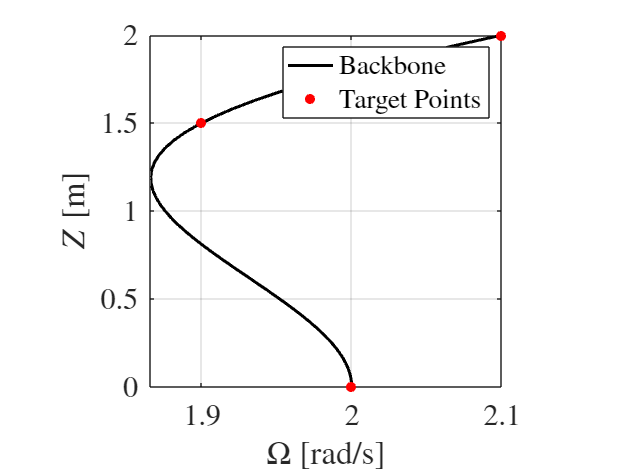

figure();
plot_backbone(omega, z, optArgs.omegaTarget, optArgs.zTarget);